%======================================
%MLX01312024_gamma3_yw
%Version 4.2
%created by Brandon Nyugen
%revised by Yoichi Watanabe
%Revision date
%2/10/2024 
%2/11/2024: 
% (1) rotmax angle = 0 if Bz > 0 and = pi if Bz < 0. Select
% (2) file selection option
%======================================

%set parameters
clearvars;  
%measurement settings
format shortG
% magnet model: D32N52 3/16, 1/8
% magnet model: D101N52 1/16, 1/32
% magnet parameters

diameter = 3/16*25.4; %mm
height = 1/8*25.4; %mm
%Br_max = 14800*0.1; %mT [specification]
Br_max =  14800*0.1;
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

Select the folder for the measured data

%selpath = uigetdir;
%file_prefix = strcat(selpath,'\sensor_');
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX02132024_D32N52_z10mm\sensor_';
file_suffix = '_averages.csv';

read the magnetic field vector data measured by 16 sensors Loop to create variables sen1, sen2, ..., sen16

for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

%determine the direction (or polarity) of magnet 
B_polarity = sign(data_matrix(1,3));

sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

%the number of data points
num_data = length(sen1);
% Create a cell array to store all rows
all_sen = cell(num_data, num_sensors);

% Access each row of each matrix and store in the cell array
for row = 1:num_data
    for sensor = 1:num_sensors
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

multipreds = [];
multifvals = [];
for t = 1:num_data
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_polarity, B_t, sensor_actual, tt, 1, num_sensors);
        nonlcon = @con;

        x0 = [0, 0, 1, 5, 5, 55];
        %x0 = [0 0 5];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        %lb = [-100 -100 0];
        %ub = [100 100 0];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

%

%calculate the distance between a point and the initital point
multiang = multipreds(:,1:3);
multiloc = multipreds(:,4:6)

multiloc =       -3.8472       -7.688       10.971
      -2.9539      0.33765       13.581
      -2.8364      -5.1645         11.3
      -4.5759     -0.74724       13.019
      -5.0706     -0.33713       12.729
        -4.74       6.2798       11.632
      -2.7962       -6.657       11.583
      -1.7161       -3.505       11.923
      -1.6823      -2.5366       11.742
       -2.991      -1.2155       13.024


%multiloc = multipreds(:,1:3);
new_multiloc = multiloc;
r0 = [multiloc(1,1) multiloc(1,2) multiloc(1,3)];
testx =sqrt(sum((new_multiloc-r0).^2, 2));

%calculate the expected displacement of measurement points r.t. the first pos.
%6x6 points
for i = 0:5
    for j= 0:5
        zi(6*i+j+1) = sqrt(i^2 + j^2);
    end
end

zi = zi';
fliers = find(testx > 10)

fliers =      6
    12
    17
    18
    22
    23
    24
    28
    29
    30


zi(fliers)

ans =             5
        5.099
       4.4721
       5.3852
       4.2426
            5
        5.831
            5
       5.6569
       6.4031


testx(fliers)

ans =        14.012
       17.195
       25.196
       11.335
       12.215
       26.223
       11.666
       10.533
       11.356
       11.691


multiloc(fliers,:)

ans =         -4.74       6.2798       11.632
       10.989      0.72515        13.16
       18.322     -0.24508       1.5919
    -0.060017        2.801       13.003
        7.946      -5.1646       12.909
       18.758     -0.18759    3.018e-05
       1.0869       2.6873       12.999
       4.1618      -1.1258       12.905
       4.4496     -0.15682       12.818
       3.9789      0.75833       12.992


all_sen

all_sen = 36×16 cell array
    {[-3.0187 0.94023 1.2764]}    {[ -3.888 2.4258 5.2829]}    {[ -0.24024 3.9052 -6.875]}    {[4.0045 2.6368 5.5316]}    {[-3.2361 -0.59217 1.4316]}    {[  -4.4298 -1.6612 5.8588]}    {[-0.27596 -2.5562 -4.9401]}    {[  4.4714 -1.8133 6.378]}    {[-2.1942 -1.5088 0.67547]}    {[ -2.4644 -3.4131 2.7217]}    {[   -0.0873 -4.828 4.4223]}    {[2.4145 -3.4546 2.7564]}    {[-1.0053 -1.1999 -0.0036058]}    {[-0.94349 -2.1853 0.46137]}    {[-0.02649 -2.8201 0.76978]}    {[0.91272 -2.2843 0.44872]}
    {[ -2.7845 1.1718 1.1077]}    {[-3.4572 2.9201 4.5157]}    {[ -0.19933 4.6018 7.5206]}    {[3.5677 3.1572 4.6837]}    {[-3.3428 -0.24285 1.5119]}    {[ -4.6372 -0.73012 6.2401]}    {[-0.27612 -1.0289 -4.2113]}    {[  4.709 -0.82064 6.762]}    {[-2.5077 -1.4464 0.88105]}    {[ -2.9547 -3.4287 3.5235]}    {[    -0.1072 4.8437 5.824]}    {[2.9051 -3.4846 3.5687]}    {[  -1.2019 -1.3015 0.094114]}    {[ -1.1811 -2.4907 0.76436]}    {[ -0.031995 -3.282 1.2318]}    {[   1.14


%zi(fliers) = [];
%testx(fliers) = [];

SSR = sum((zi - testx).^2)

SSR =        1723.1


SST = sum((zi - mean(testx)).^2)

SST =        1067.3


R2 = 1 - SSR/SST

R2 =       -0.6144



sorts = [testx, zi]

sorts =             0            0
       8.4865            1
       2.7381            2
       7.2731            3
       7.6564            4
       14.012            5
       1.5943            1
         4.79       1.4142
       5.6406       2.2361
       6.8438       3.1623


sorts = sort(sorts,1)

sorts =             0            0
       1.5943            1
       2.7381            1
       3.4787       1.4142
         4.79            2
       5.1275            2
       5.6406       2.2361
       5.8557       2.2361
       5.8876       2.8284
       5.9627            3


diff = sorts(:,1) - sorts(:,2)

diff =             0
      0.59426
       1.7381
       2.0645
         2.79
       3.1275
       3.4045
       3.6196
       3.0592
       2.9627


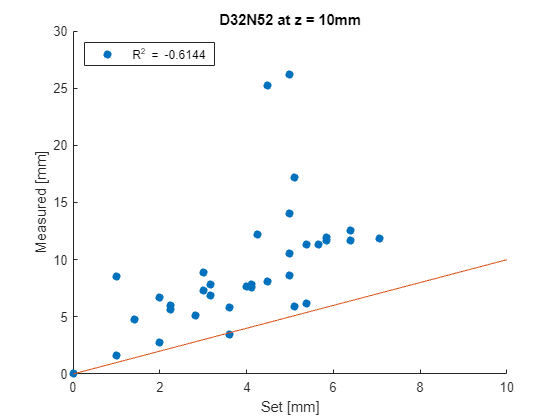


figure(1)
scatter(zi, testx, 'filled')
hold on;
plot(0:10,0:10)
xlabel("Set [mm]")
ylabel('Measured [mm]')
legend(['R^2 = ', num2str(R2)], Location = 'northwest')
title('D32N52 at z = 10mm')
hold off;

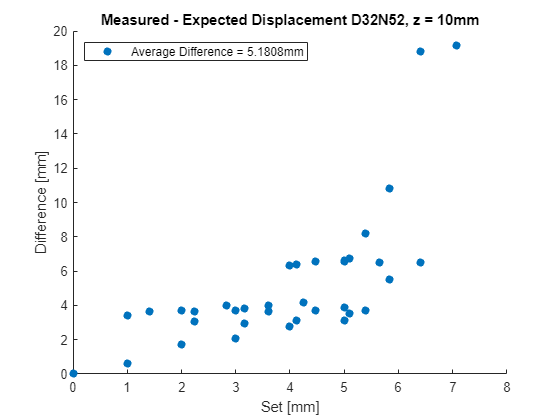

scatter(zi, diff, "filled")
hold on;
ylabel('Difference [mm]')
xlabel('Set [mm]')
title('Measured - Expected Displacement D32N52, z = 10mm')
legend(['Average Difference = ', num2str(mean(diff)), 'mm'], Location='northwest')
hold off;

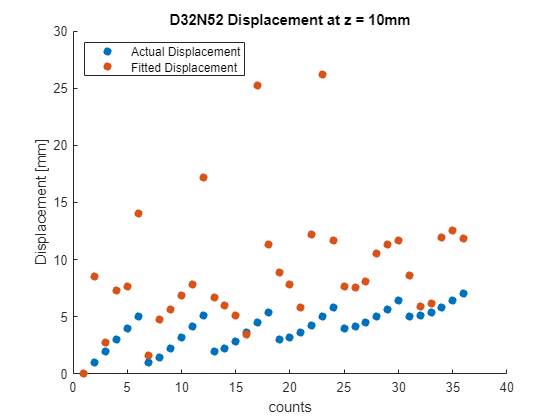

disp = zi;
multidisp = testx;
figure(2)
scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement [mm]')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
title('D32N52 Displacement at z = 10mm')
hold off;

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function mm = mmcost(v, B_p, B_t, sensor_grid, sensor_data, s1, s2)
%modifed by Yoichi Watanabe, last updated on 2/10/2024
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)]; 
    %x y z coordinate of the center of num_sensors arrays
    %H_0 = repelem([0 0 1], 1, 1);
    %loc = [v(1) v(2) v(3)];
    s = sensor_data;
    %--------rotate the array plane relative to the global coordinate
    epsilon = 1e-12;
    n1 = [1 0 0];
    n2 = [0 1 0];
    n3 = [0 0 1];
    n_global = [n1; n2; n3];
    h0_m = norm(H_0)+epsilon;
    H_1 = H_0./h0_m;
    rotmtx = rotation_mat(n3, H_1);
    rotx = @(t) [1 0 0; 0 cos(t) -sin(t) ; 0 sin(t) cos(t)];
    rot_angle=0; %changed from pi to 0 (2/10/2024)
    if B_p == 1
        rot_angle = 0;
    else
        rot_angle = pi;
    end
    X_t = rotx(rot_angle)*sensor_grid';
    sensor_grid_t = (rotmtx * X_t)';
    %------------------------------------
    mm = 0;
    for i = s1:s2
        X = sensor_grid_t(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        %changed H_0 to H_1 on 2/10/2024
        mm = mm + sum((s(3*i-2:3*i) - ...
            B_t * (3 * dot(H_1, X, 2).* X./ R.^5 - H_1./ R.^3)).^2);
    end
end

function R = rotation_mat(a, b)
u = a'/norm(a');                      % a and b must be column vectors
v = b'/norm(b');                      % of equal length
N = length(u);
S = reflection( eye(N), v+u );      % S*u = -v, S*v = -u 
R = reflection( S, v );             % v = R*u
end

function v = reflection( u, n )     % Reflection of u on hyperplane n.
%
% u can be a matrix. u and v must have the same number of rows.

v = u - 2 * n * (n'*u) / (n'*n);
end